# 结构化编程

## 流程控制语句

a = 0

a = 0

% if语句
if rem(a, 2) == 0 % 除后的余数为0
	disp('a is even'); % 显示变量的值，相当于 cout
else
	disp('a is odd');
end

a is even


help rem

 rem - 除后的余数
    此 MATLAB 函数 返回 a 除以 b 后的余数，其中 a 是被除数，b 是除数。此函数通常称为求余
    运算，表达式为 r = a - b.*fix(a./b)。rem 函数遵从 rem(a,0) 是 NaN 的约定。

    r = rem(a,b)

    输入参数
        a - 被除数
            标量 | 向量 | 矩阵 | 多维数组
        b - 除数
            标量 | 向量 | 矩阵 | 多维数组

    打开示例
        标量被除后的余数
        向量被除后的余数
        正值和负值被除后的余数
        浮点值被除后的余数

    另请参阅 mod

    已在 R2006a 之前的 MATLAB 中引入
    

help disp

 disp - 显示变量的值
    此 MATLAB 函数 显示变量 X 的值，而不打印变量名称。显示变量的另一种方法是键入它的名
    称，这种方法会在值前面显示一个前导X =。

    disp(X)

    输入参数
        X - 输入数组
            数组

    打开示例
        显示变量值
        显示矩阵及其列标签
        在同一行上显示多个变量

    另请参阅 format, int2str, num2str, sprintf, fprintf, formattedDisplayText

    已在 R2006a 之前的 MATLAB 中引入
    <a href

% while语句
n = 1;
while prod(1:n) < 1e100 % 从 1 开始到 n 的乘积 1e100(10的100次方)即10乘100次
	n = n + 1;
end
help prod

 prod - 数组元素的乘积
    此 MATLAB 函数 返回 A 的数组元素的乘积。 如果 A 是向量，则 prod(A) 返回元素的乘积。
    如果 A 为非空矩阵，则 prod(A) 将 A 的各列视为向量，并返回一个包含每列乘积的行向量。
    如果 A 为 0×0 空矩阵，prod(A) 返回 1。 如果 A 为多维数组，则 prod(A) 沿第一个非单
    一维度运算并返回乘积数组。此维度的大小将减少至 1，而所有其他维度的大小保持不变。

    B = prod(A)
    B = prod(A,'all')
    B = prod(A,dim)
    B = prod(A,vecdim)
    B = prod(___,outtype)
    B = prod(___,nanflag)

    输入参数
        A - 输入数组
            向量 | 矩阵 | 多维数组
        dim - 沿其运算的维度
            正整数标量
        vecdim - 维度向量
            正整数向量
        

1e2 % 10*10=100

ans = 100

1:70 % 1 到 70 的数组

ans =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


% for语句
for n=1:10
	j(n)=2^n;
end
disp(j)

  列 1 至 9

           2           4           8          16          32          64         128         256         512

  列 10

        1024



% break语句
x = 2; k = 0; error = inf;
error_threshold = 1e-32;
while error > error_threshold
    if k > 100
    	break
    end
    x = x - sin(x)/cos(x);
    error = abs(x - pi);
    k = k + 1;
end
disp(x)

    3.1416



## 循环语句应尽量预先分配内存空间

tic
for ii = 1:2000
    for jj = 1:2000
        A(ii,jj) = ii + jj;
    end
end
toc % 计时

历时 3.394724 秒。


help tic

 tic - 启动秒表计时器
    此 MATLAB 函数 与 toc 函数结合使用，可以测量经过的时间。tic 函数记录当前时间，toc
    函数使用记录的值计算经过的时间。

    tic
    timerVal = tic

    打开示例
        测量创建随机矩阵的时间
        测量自 tic 调用以来经过的不同时间间隔
        使用多个 tic 调用来测量时间

    另请参阅 clock, cputime, etime, profile, timeit, toc

    已在 R2006a 之前的 MATLAB 中引入
    tic 的文档



tic
A = zeros(2000, 2000);		% 预先为变量分配内存空间
for ii = 1:size(A,1)
    for jj = 1:size(A,2)
        A(ii,jj) = ii + jj;
    end
end
toc

历时 0.038247 秒。


## 编写脚本时应注意的问题

% 在脚本开头应添加语句清空工作区
clear all	% 清空工作区内存中的变量
close all 	% 关闭之前程序绘制的图像
clc			% 清空之前程序在终端的输出

% 在运算和赋值语句后应添加分号;抑制输出

% 使用省略号...拼接多行语句
a = ...
    2

a = 2

## 函数

edit(which('mean.m')) % which-源代码文件位置 edit-内置函数源代码

## 以函数名.m文件形式定义函数

格式

- function [输出变量名] = 函数名(输入变量名) 

- % 函数的文档

- 函数代码

freebody(0, 0, 2);			% 得到 19.6000
freebody(0, 0, [0 1 2 3]);	% 得到 [0 4.9000 19.6000 44.1000]
freebody(0, 0, [0 1; 2 3])	% 得到 [0 4.9000; 19.6000 44.1000]

## 定义函数

F2C()

## 以函数句柄形式定义函数

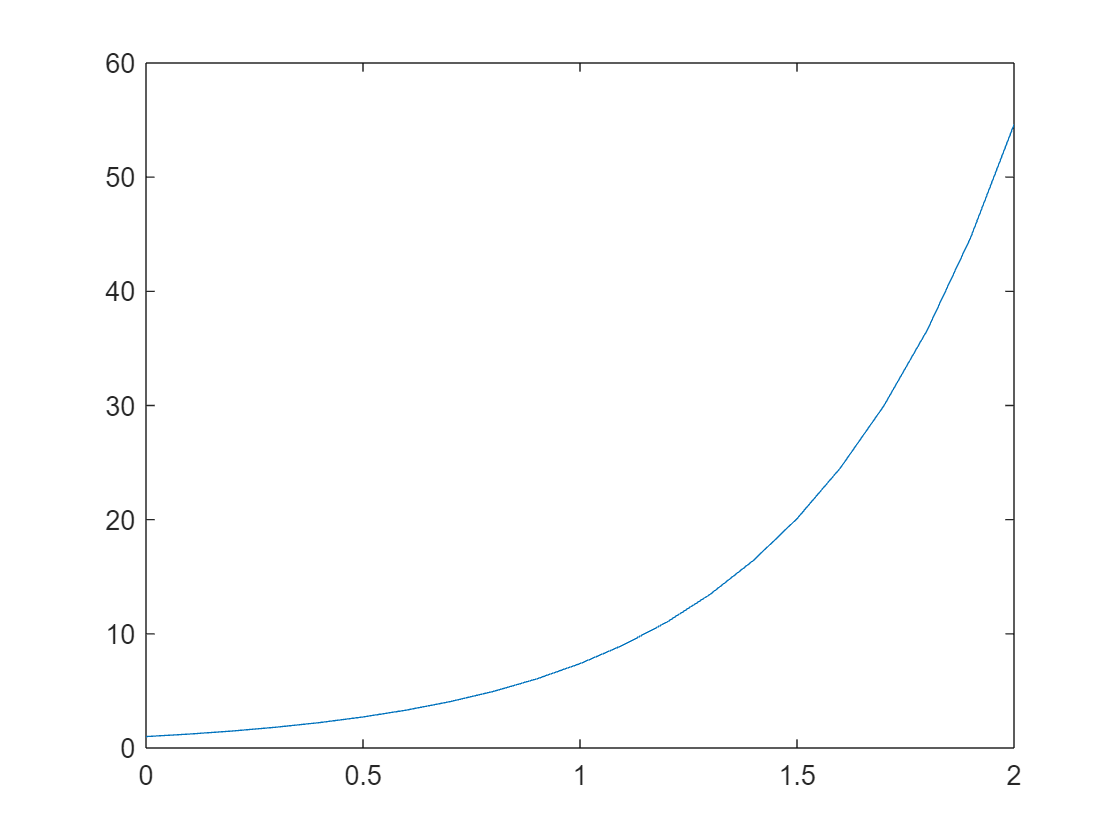

% 函数句柄 = @(输入变量) 输出变量 
f = @(x) exp(2*x);
x = 0:0.1:2;
plot(x, f(x));